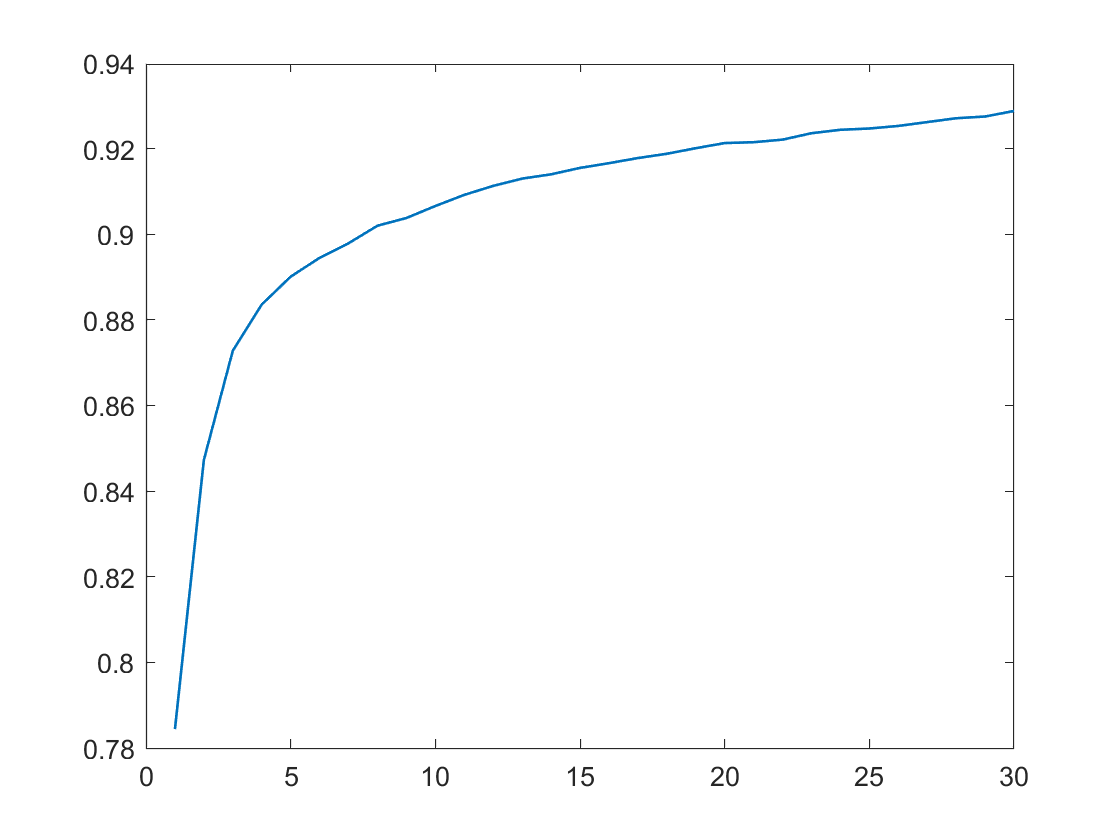

% parameters
epochs = 30;
hidden_dim = 100;
alpha = 0.00005;

X_train = load_images("train-images.idx3-ubyte", 2, 'double');
Y_train = load_labels("train-labels.idx1-ubyte");
X_test = load_images("t10k-images.idx3-ubyte", 2, 'double');
Y_test = load_labels("t10k-labels.idx1-ubyte");

% create one-hot encoding for Y_train and Y_test
Y_train = onehotencode(Y_train, 2);
Y_test = onehotencode(Y_test, 2);
Y_train = Y_train';
Y_test = Y_test';

input_dim = size(X_train, 1);
output_dim = size(Y_train, 1);
train_num = size(X_train, 2);
test_num = size(X_test, 2);

% create weight matrices and biases
w1 = randn(hidden_dim, input_dim)*sqrt(2/784);
w2 = randn(output_dim, hidden_dim)*sqrt(2/hidden_dim);
b1 = randn(hidden_dim, 1);
b2 = randn(output_dim, 1);

% mean squared error
error_train = zeros(1, epochs);
error_test = zeros(1, epochs);
accuracy_test = zeros(1, epochs); 

% Train
for it = 1:epochs
    errors = zeros(1, train_num);
    for ind = 1:train_num
        x = X_train(:, ind);
        y = Y_train(:, ind);
        
        [a1, a2, in1, in2] = BP_forward(x, w1, w2, b1, b2);
                  
        % cross entropy loss
        errors(1, ind) = -sum(y.*log(a2));
        
        d2 = a2-y;
        d1 = (w2'*d2).*(in1>0);
        
        w2 = w2 - alpha*d2*a1';
        w1 = w1 - alpha*d1*x';  
        
        b2 = b2 - alpha*d2;
        b1 = b1 - alpha*d1;
    end
    error_train(:, it) = mean(errors);
    [accuracy_test(:, it), error_test(:, it)] = BP_test(X_test, Y_test, w1, w2, b1, b2);
end
plot(accuracy_test, 'LineWidth', 1)

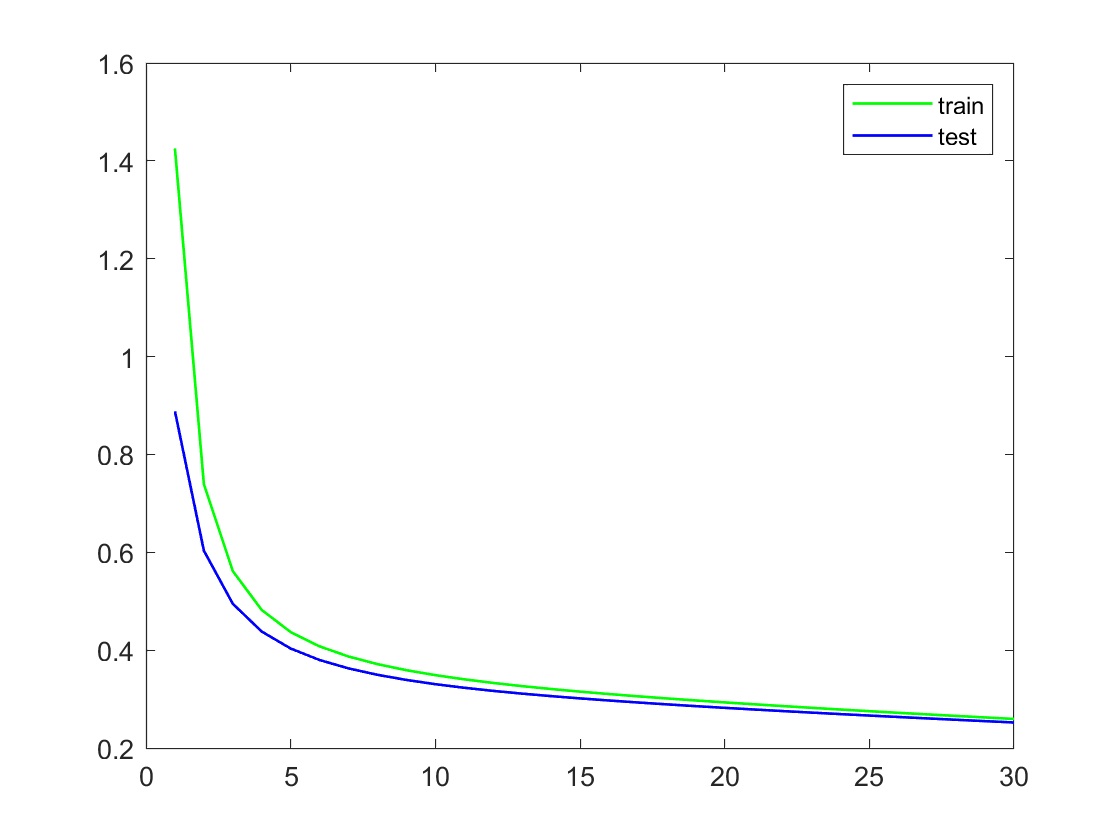

plot(1:epochs, error_train, 'g', 1:epochs, error_test, 'b', 'LineWidth', 1)
legend('train', 'test')

save BP.mat w1 w2 b1 b2